zerLoad in data from the work space

data=readtable("dataClean.csv");


electrical_load = data.AC;

% Prepare data for training
input_window_size = 168; % 7 days of hourly data
output_window_size = 24; % 1 day ahead prediction
total_window_size = input_window_size + output_window_size;

% Prepare the input and target series
n = length(electrical_load)/input_window_size;
X = [data.AC(1:end-1)];

T = data.AC(2:end);
% 
% for i = 1:(n -  1)
%     idx=1+(i-1)*input_window_size;
%     X(:,i) =  electrical_load(idx:idx + input_window_size - 1)';
%     T(:,i) =  electrical_load(idx + input_window_size:idx + total_window_size - 1)';
% end


% Split data into training and testing sets
train_ratio = 0.7;
num_train = floor(length(X) * train_ratio);
X_train = X(1:num_train);
T_train = T(1:num_train);
X_test = X(num_train+1:end);
T_test = T(num_train+1:end);

% Create and Train Neural Network

opt = struct("ShowPlots",true,"MaxObjectiveEvaluations",100);

% Define hyperparameters to optimize
params = hyperparameters("fitrnet",X_train,"MPG");
for ii = 1:length(params)
    disp(ii);disp(params(ii))
end

     1

  optimizableVariable with properties:

         Name: 'NumLayers'
        Range: [1 3]
         Type: 'integer'
    Transform: 'none'
     Optimize: 1

     2

  optimizableVariable with properties:

         Name: 'Activations'
        Range: {'relu'  'tanh'  'sigmoid'  'none'}
         Type: 'categorical'
    Transform: 'none'
     Optimize: 1

     3

  optimizableVariable with properties:

         Name: 'Standardize'
        Range: {'true'  'false'}
         Type: 'categorical'
    Transform: 'none'
     Optimize: 1

     4

  optimizableVariable with properties:

         Name: 'Lambda'
        Range: [1.6311e-09 16.3106]
         Type: 'real'
    Transform: 'log'
     Opt

|============================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda | LayerWeights-| LayerBiasesI-|            LayerSizes |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | Initializer  | nitializer   |                       |
|============================================================================================================================================|
|    1 | Best   |      5.7182 |      29.637 |      5.7182 |      5.7182 |       10.414 |           he |         ones | [ 23  33   7 113]     |
|    2 | Accept |      7.5171 |      52.048 |      5.7182 |      5.8469 |     0.019749 |           he |        zeros | [  1 236 258   1   5] |
|    3 | Accept |      6.9713 |      62.978 |      5.7182 |      5.7186 |   8.2984e-09 |       glorot |        zeros | [  1  95 223]         |

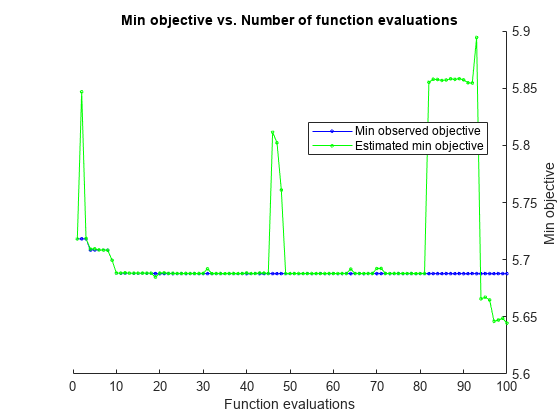


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 1255.5679 seconds
Total objective function evaluation time: 1186.0166

Best observed feasible point:
     Lambda     LayerWeightsInitializer    LayerBiasesInitializer             LayerSizes          
    ________    _______________________    ______________________    _____________________________

    0.029054              he                       zeros             6      9     18    163     12

Observed objective function value = 5.6878
Estimated objective function value = 5.7627
Function evaluation time = 78.2808

Best estimated feasible point (according to models):
    Lambda     LayerWeightsInitializer    LayerBiasesInitializer


params(1).Range = [1 5] ;

params(2).Optimize = false ;

params(3).Optimize = false;

params(5).Optimize = true;
params(6).Optimize = true;
params(10).Optimize = true;
params(11).Optimize = true;
% Fit the network using hyperparameter optimization
net = fitrnet(X_train, T_train, ...
    'Standardize', true, ...
    'Activations', 'relu', ...
    'OptimizeHyperparameters', params, ...
    'HyperparameterOptimizationOptions', opt);

net

net =   RegressionNeuralNetwork
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 6131
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           LayerSizes: [1 57]
                          Activations: 'relu'
                OutputLayerActivation: 'none'
                               Solver: 'LBFGS'
                      ConvergenceInfo: [1×1 struct]
                      TrainingHistory: [147×7 table]


  Properties, Methods


% Perform Forecast


timeStep= 1;
for j = 1:(floor(length(X_test)/timeStep)-ceil(24/timeStep)-71)
   
    offset = j*timeStep+71 ;
    
    input = X_test(1:offset); 
    first_forecast = predict(net, input);
    Yin = first_forecast(end:end);
    Y = zeros(24,1);
    Y(1) = Yin;
      
    for i=2:24
        input = [input(2:end)' Y(i-1)'];
        input = input';
        YNext = predict(net, input);
        Y(i)  = [YNext(end:end)];

    end
    
    Ypred{j}(:) = Y(:);
    Yactual{j}(:) = T_test(offset:offset+23);
end

YmapeHr = zeros(24,1);
Yrmse   = zeros(24,1);
YseCal = zeros(24,1);

for i=1:j
Ymape{i}(:) = abs(Yactual{i} - Ypred{i})./(Yactual{i})*100;
YmapeHr(:) = YmapeHr + Ymape{i}(:);

YseCal(:) = YseCal(:) + (Yactual{i}(:) - Ypred{i}(:)).^2;

YintMape(i) = (abs(trapz(Yactual{i}) - trapz(Ypred{i}))/(trapz(Yactual{i})))*100;

YintRmse(i) = ((trapz(Yactual{i})-trapz(Ypred{i}))/24)^2;

YintTotalRmse(i) = ((trapz(Yactual{i})-trapz(Ypred{i})))^2;

end



YmapeHr = YmapeHr./j;
Yrmse = sqrt(YseCal./j);

yMeanRmse = sqrt(mean(YseCal./j));

ACintMape = mean(YintMape)

ACintMape = 14.6902

ACtotalIntRmse = sqrt(mean(YintTotalRmse))

ACtotalIntRmse = 637.2020

ACintRmse = sqrt(mean(YintRmse))

ACintRmse = 26.5501

hourlyACmape = YmapeHr

hourlyACmape =     7.5188
   13.2293
   17.7004
   21.3236
   24.3791
   26.9355
   29.0956
   30.7567
   32.2454
   33.3447


hourlyACrmse = Yrmse

hourlyACrmse =    18.7522
   29.3396
   37.1607
   43.3301
   48.3429
   52.2370
   55.3224
   57.6064
   59.4712
   60.7114


ACrmseMean = yMeanRmse

ACrmseMean = 50.6032


save('NN_AC', 'hourlyACmape','hourlyACrmse','ACrmseMean','ACintMape','ACintRmse','ACtotalIntRmse')

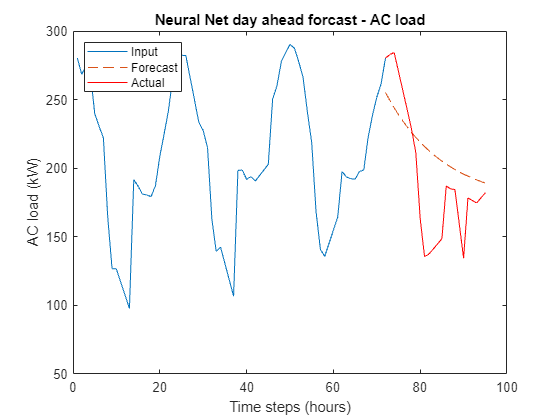


plot(1:72 , T_test(1:72))

hold on
plot(72:95, Ypred{1},"--")
plot(72:95, Yactual{1},"r")

ylabel("AC load (kW)")
xlabel("Time steps (hours)")
title("Neural Net day ahead forcast - AC load")
legend("Input", "Forecast", "Actual", "Location","northwest")

hold off

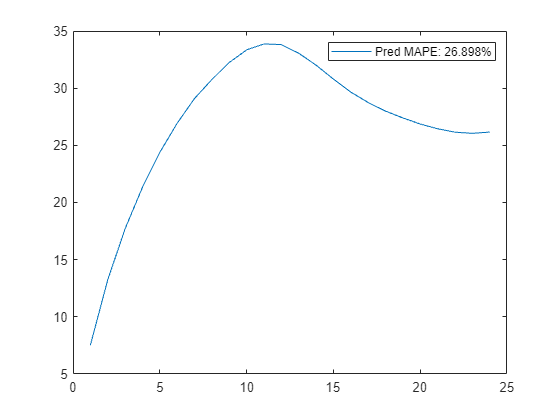




plot(YmapeHr)
legend("Pred MAPE: " + mean(YmapeHr) +"%")

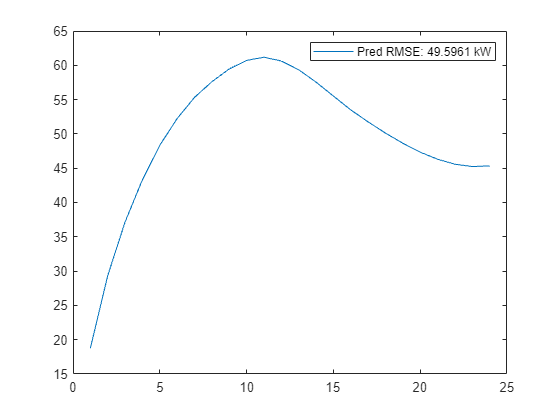


plot(Yrmse)
legend("Pred RMSE: " + mean(Yrmse) +" kW")